MA 1024 Lab 1

Daniel Coburn, Aidan Nolde

1)

syms f(x,y) z1(x,y) z2(x,y)
f(x,y)= abs(x) + abs(y)

$$f(x, y) = \left|x\right|+\left|y\right|$$

z1(x,y)= 1

$$z1(x, y) = 1$$

z2(x,y)= .4

$$z2(x, y) = \frac{2}{5}$$

Plane equations for z = 1 & z = 0.4

fsurf(f,[-1 1 -1 1])
xlabel('x axis'), ylabel('yaxis'), zlabel('z axis')
text(0,0,0, 'local min')

There is no local max. The local min is at (0,0,0)

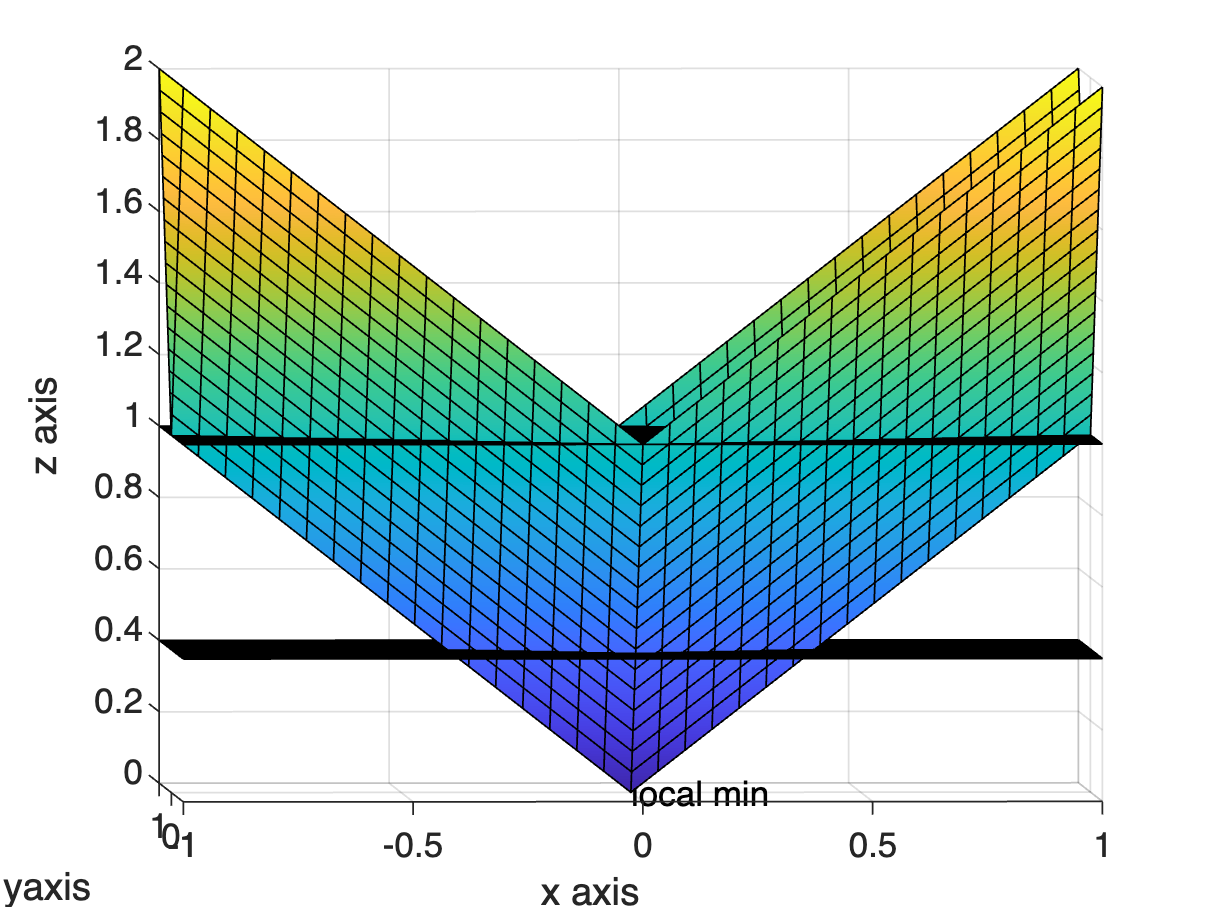

hold on
fsurf(z1, [-1 1 -1 1])
fsurf(z2, [-1 1 -1 1])
view([-1.5 1.5])
hold off

LevelCurves1c = linspace(-1,1,50)

LevelCurves1c =    -1.0000   -0.9592   -0.9184   -0.8776   -0.8367   -0.7959   -0.7551   -0.7143   -0.6735   -0.6327   -0.5918   -0.5510   -0.5102   -0.4694   -0.4286   -0.3878   -0.3469   -0.3061   -0.2653   -0.2245   -0.1837   -0.1429   -0.1020   -0.0612   -0.0204    0.0204    0.0612    0.1020    0.1429    0.1837    0.2245    0.2653    0.3061    0.3469    0.3878    0.4286    0.4694    0.5102    0.5510    0.5918    0.6327    0.6735    0.7143    0.7551    0.7959    0.8367    0.8776    0.9184    0.9592    1.0000


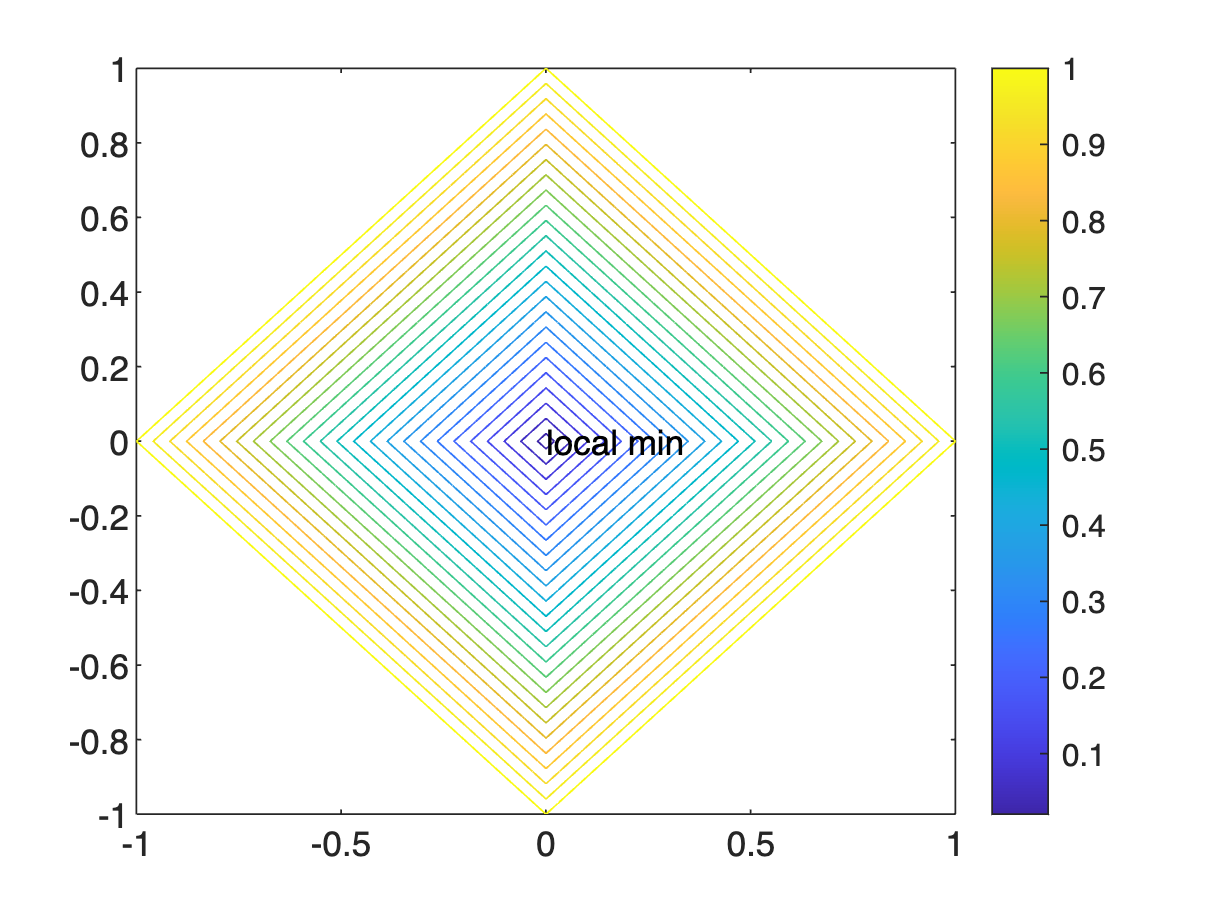

fcontour(f, [-1 1 -1 1], 'LevelList', LevelCurves1c)
colorbar
text(0,0,0,'local min')

The contour map shows that the point at 0,0,0 is a local min becuase there are no cross sections below it and, it is a point. This indicates that it is the lowest point in the domain so it is the only point with the most extreme color on the contour plot. A maximum value would have no cross sections above it since it is the highest point on the graph. It also has the most extreme opposite color on the contour plot.

2)

syms g(x,y)
g(x,y)= y^2 - y^4 - x^2

$$g(x, y) = -x^{2}-y^{4}+y^{2}$$

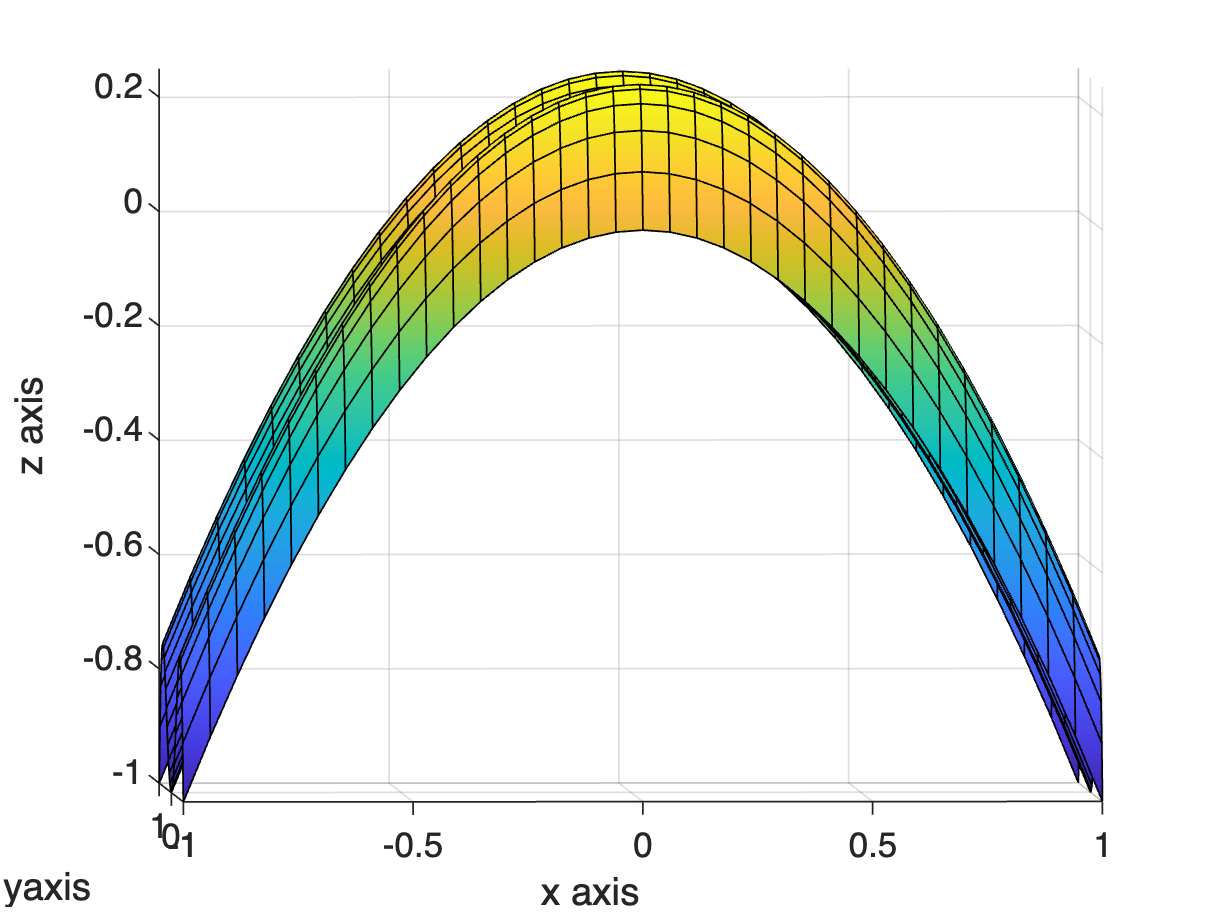

fsurf(g,[-1 1 -1 1])
xlabel('x axis'), ylabel('yaxis'), zlabel('z axis')
text(0, -0.75, 0.3, 'local max')
text(0, 0.5, 0.3, 'local max')
text(0,-0.075,0.05, 'saddle')
hold on
view([-1.5 1.5])
hold off

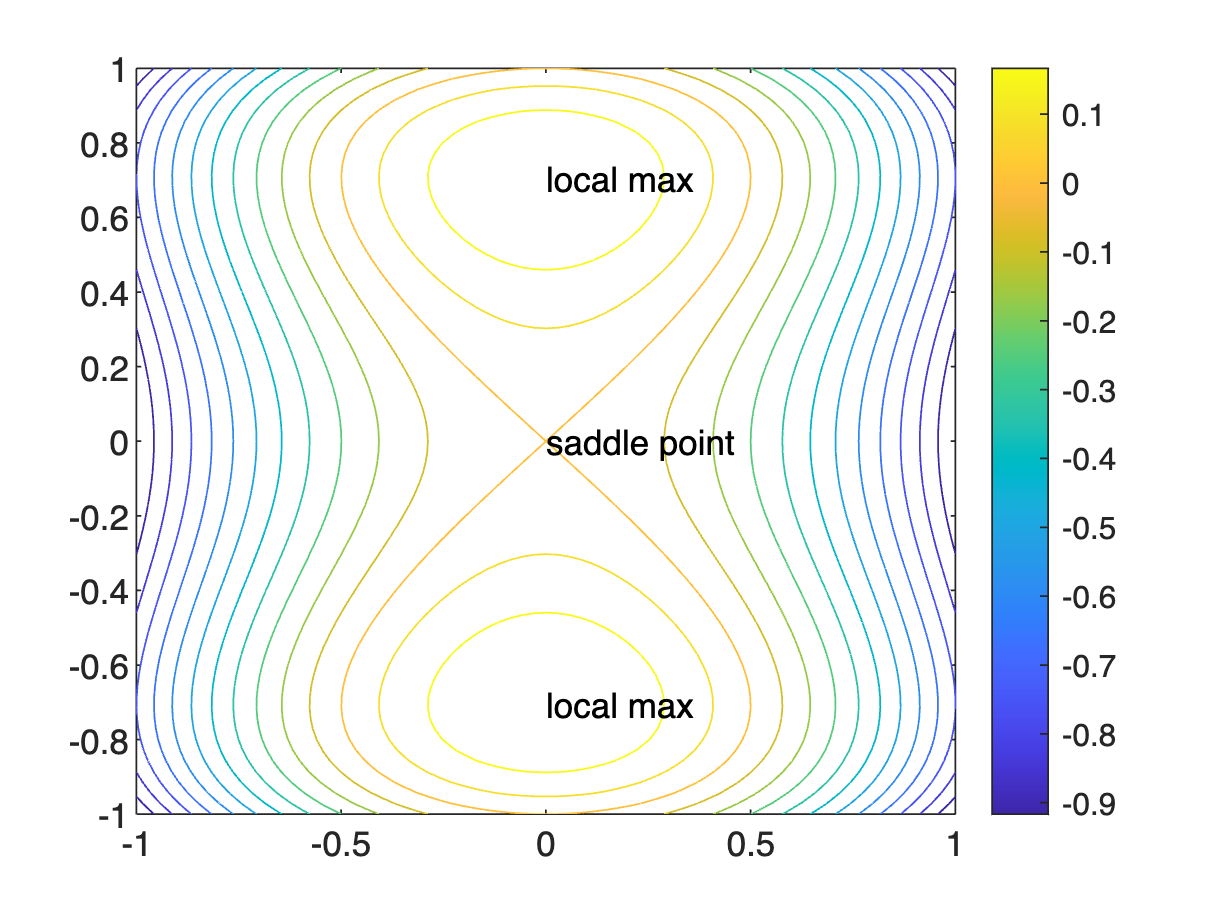

LevelCurves1c = linspace(-1,1,25);
fcontour(g, [-1 1 -1 1], 'LevelList', LevelCurves1c)
colorbar
text(0,0,'saddle point')
text(0, -0.705, 'local max')
text(0, 0.705,  'local max')

The level curve of a saddle point is a cross becyase this is where the graph is going to "pivot". If we where to make an aproximate graph of the function with segmnets of planes, this cross is where the direction of the planes is going to change, and the plane segment at the cross location is going to be parallel to the z-azis.

3)

syms i(x, y)
i(x,y) = 3*x - x^3 - 2*y^2 + y^4

$$i(x, y) = -x^{3}+3\,x+y^{4}-2\,y^{2}$$

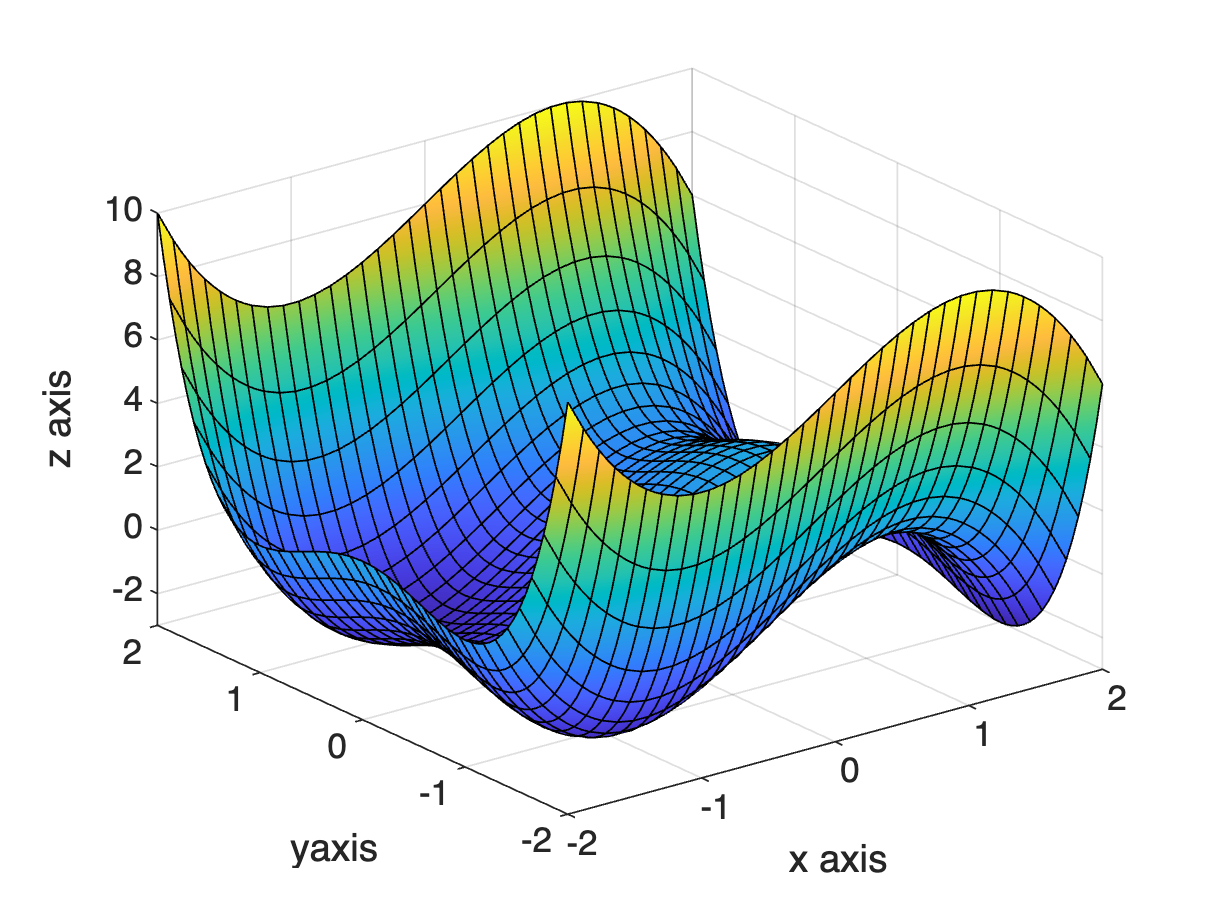

fsurf(i,[-2 2 -2 2])
xlabel('x axis'), ylabel('yaxis'), zlabel('z axis')

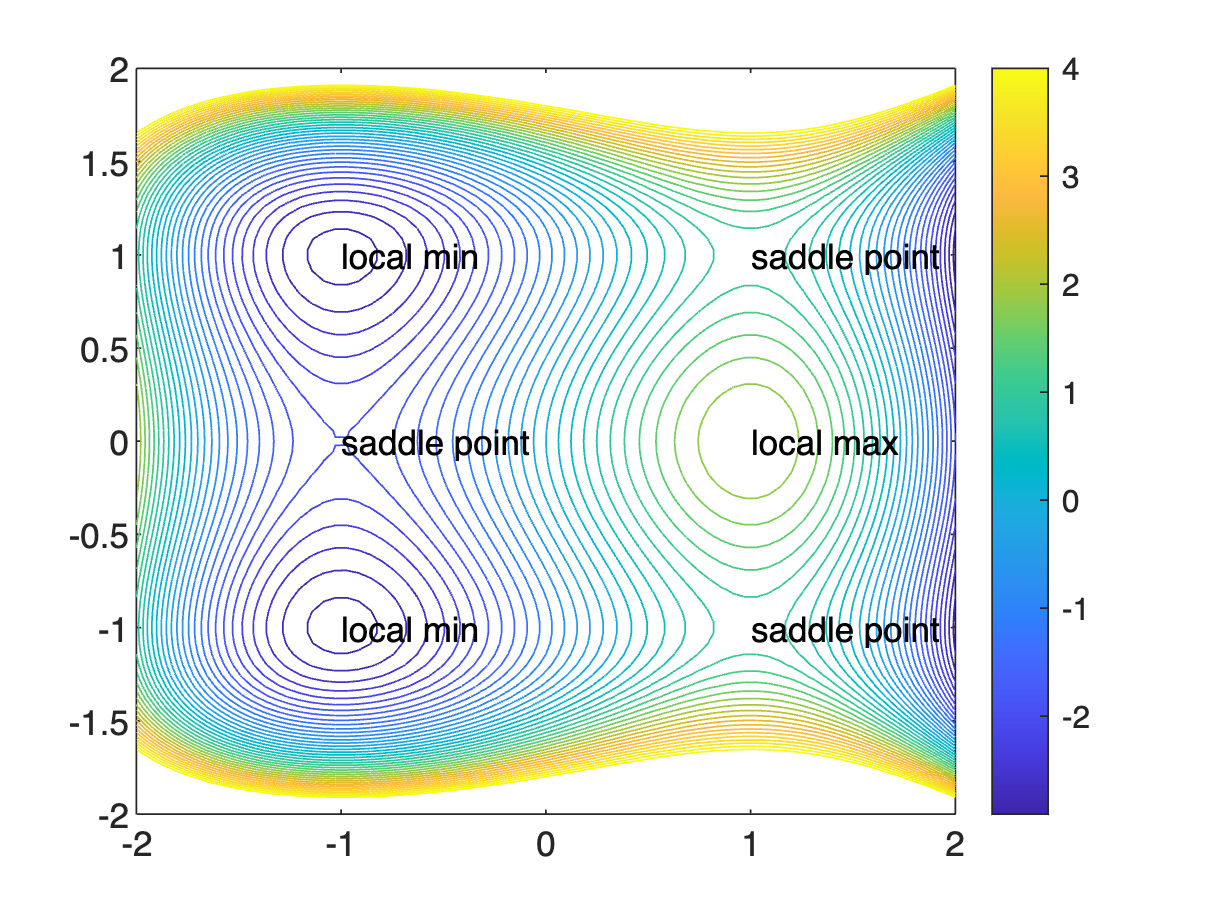

LevelCurves3b = linspace(-4, 4, 45);
fcontour(i, [-2 2 -2 2], 'LevelList', LevelCurves3b)
colorbar
text(1, 0, 'local max')
text(1, 1, 'saddle point')
text(1, -1, 'saddle point')
text(-1, 1, 'local min')
text(-1, -1, 'local min')
text(-1, 0, 'saddle point')

4)

syms j(x,y) 
j(x, y) = 5*exp(-(x/15)^2 - (y/15)^2) + 10*exp(-(x+10)^2-(y+10)^2)

$$j(x, y) = 5\,{\mathrm{e}}^{-\frac{x^{2}}{225}-\frac{y^{2}}{225}}+10\,{\mathrm{e}}^{-{\left(x+10\right)}^{2}-{\left(y+10\right)}^{2}}$$

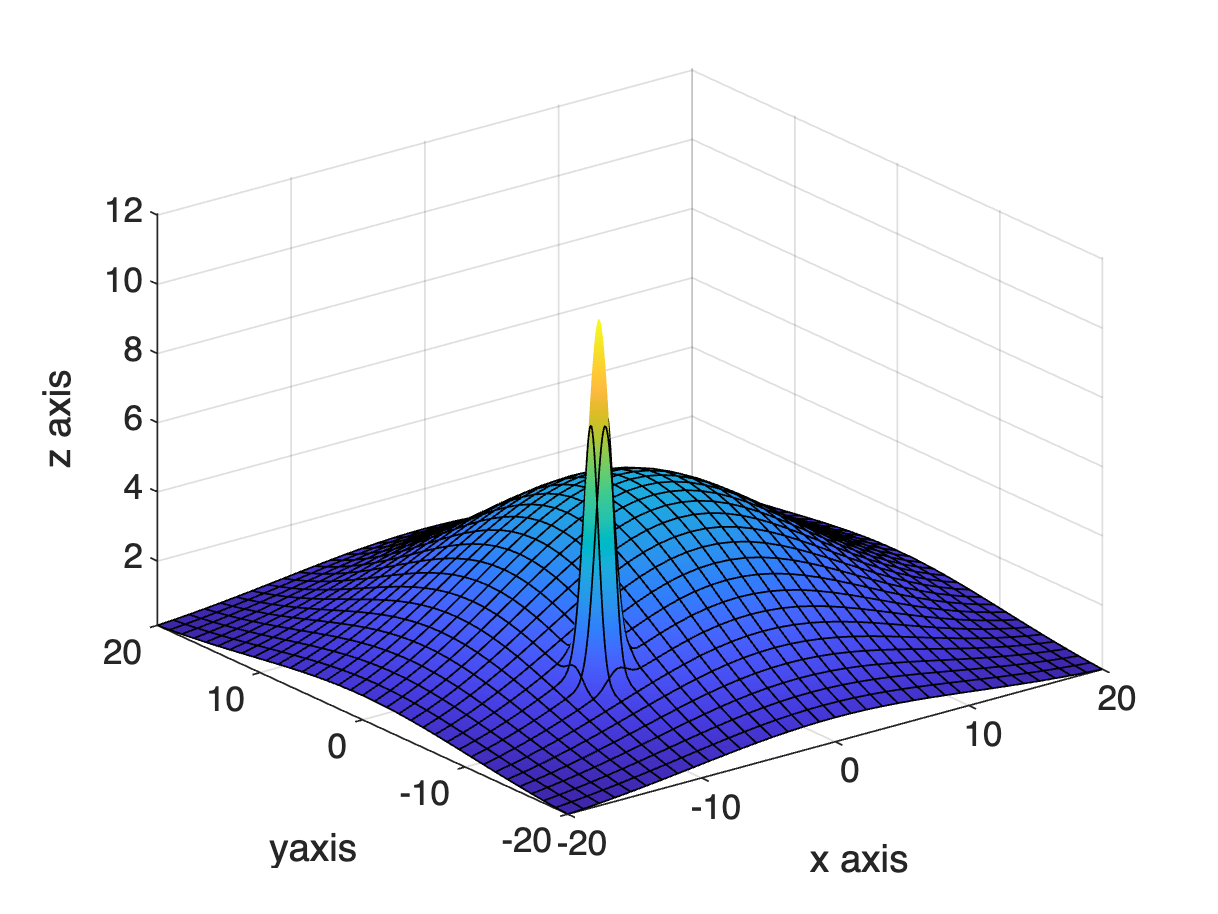

fsurf(j, [-20 20 -20 20])
xlabel('x axis'), ylabel('yaxis'), zlabel('z axis')

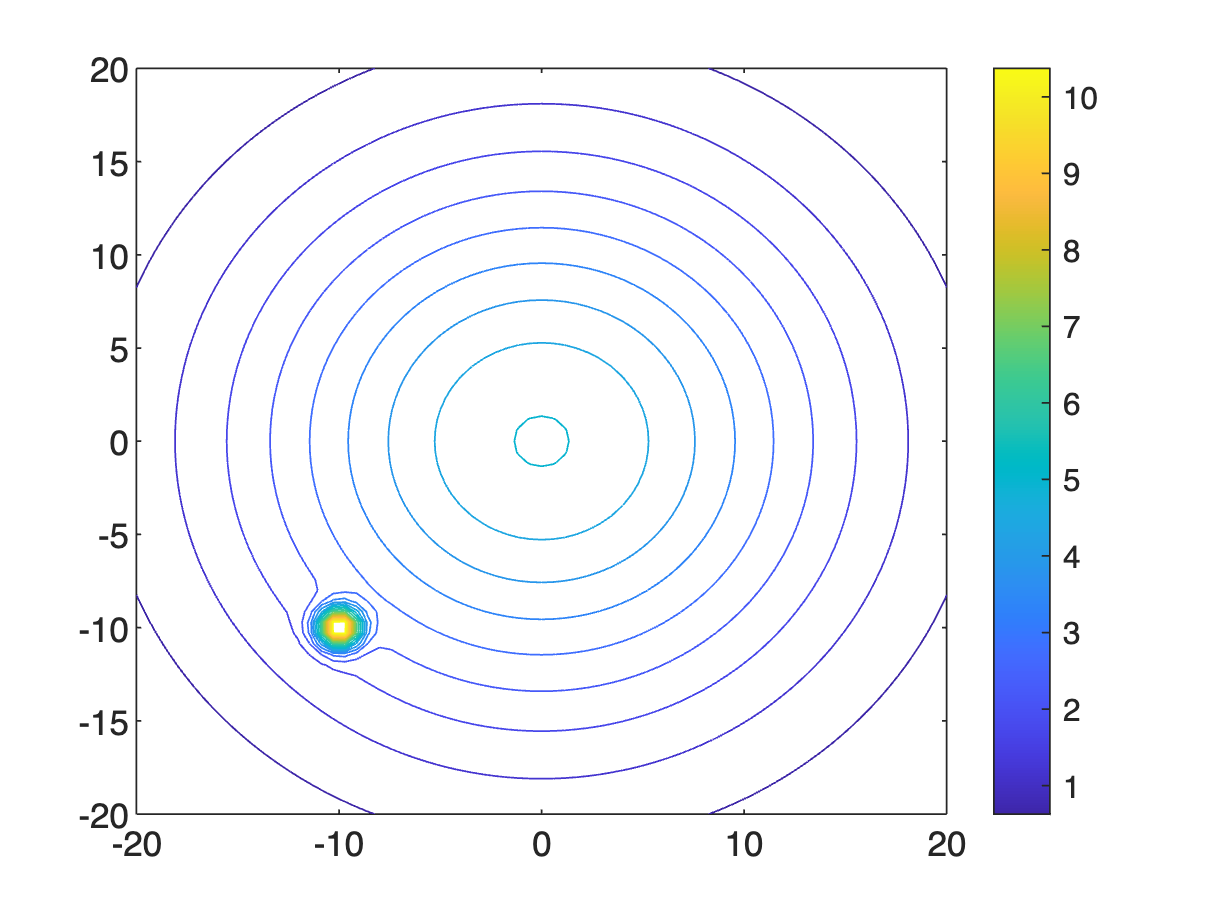

LevelCurves4a = linspace(-1, 12, 25);
fcontour(j, [-20 20 -20 20], 'LevelList', LevelCurves4a)
colorbar

The distance between level curves is an estimate of the slope of the "walls" of the surface. when walls are closer together, for a given step in the z-axis that measn that the wall is "steeper", or the delta in the z-axis for a given delta in the xy-plane is larger.